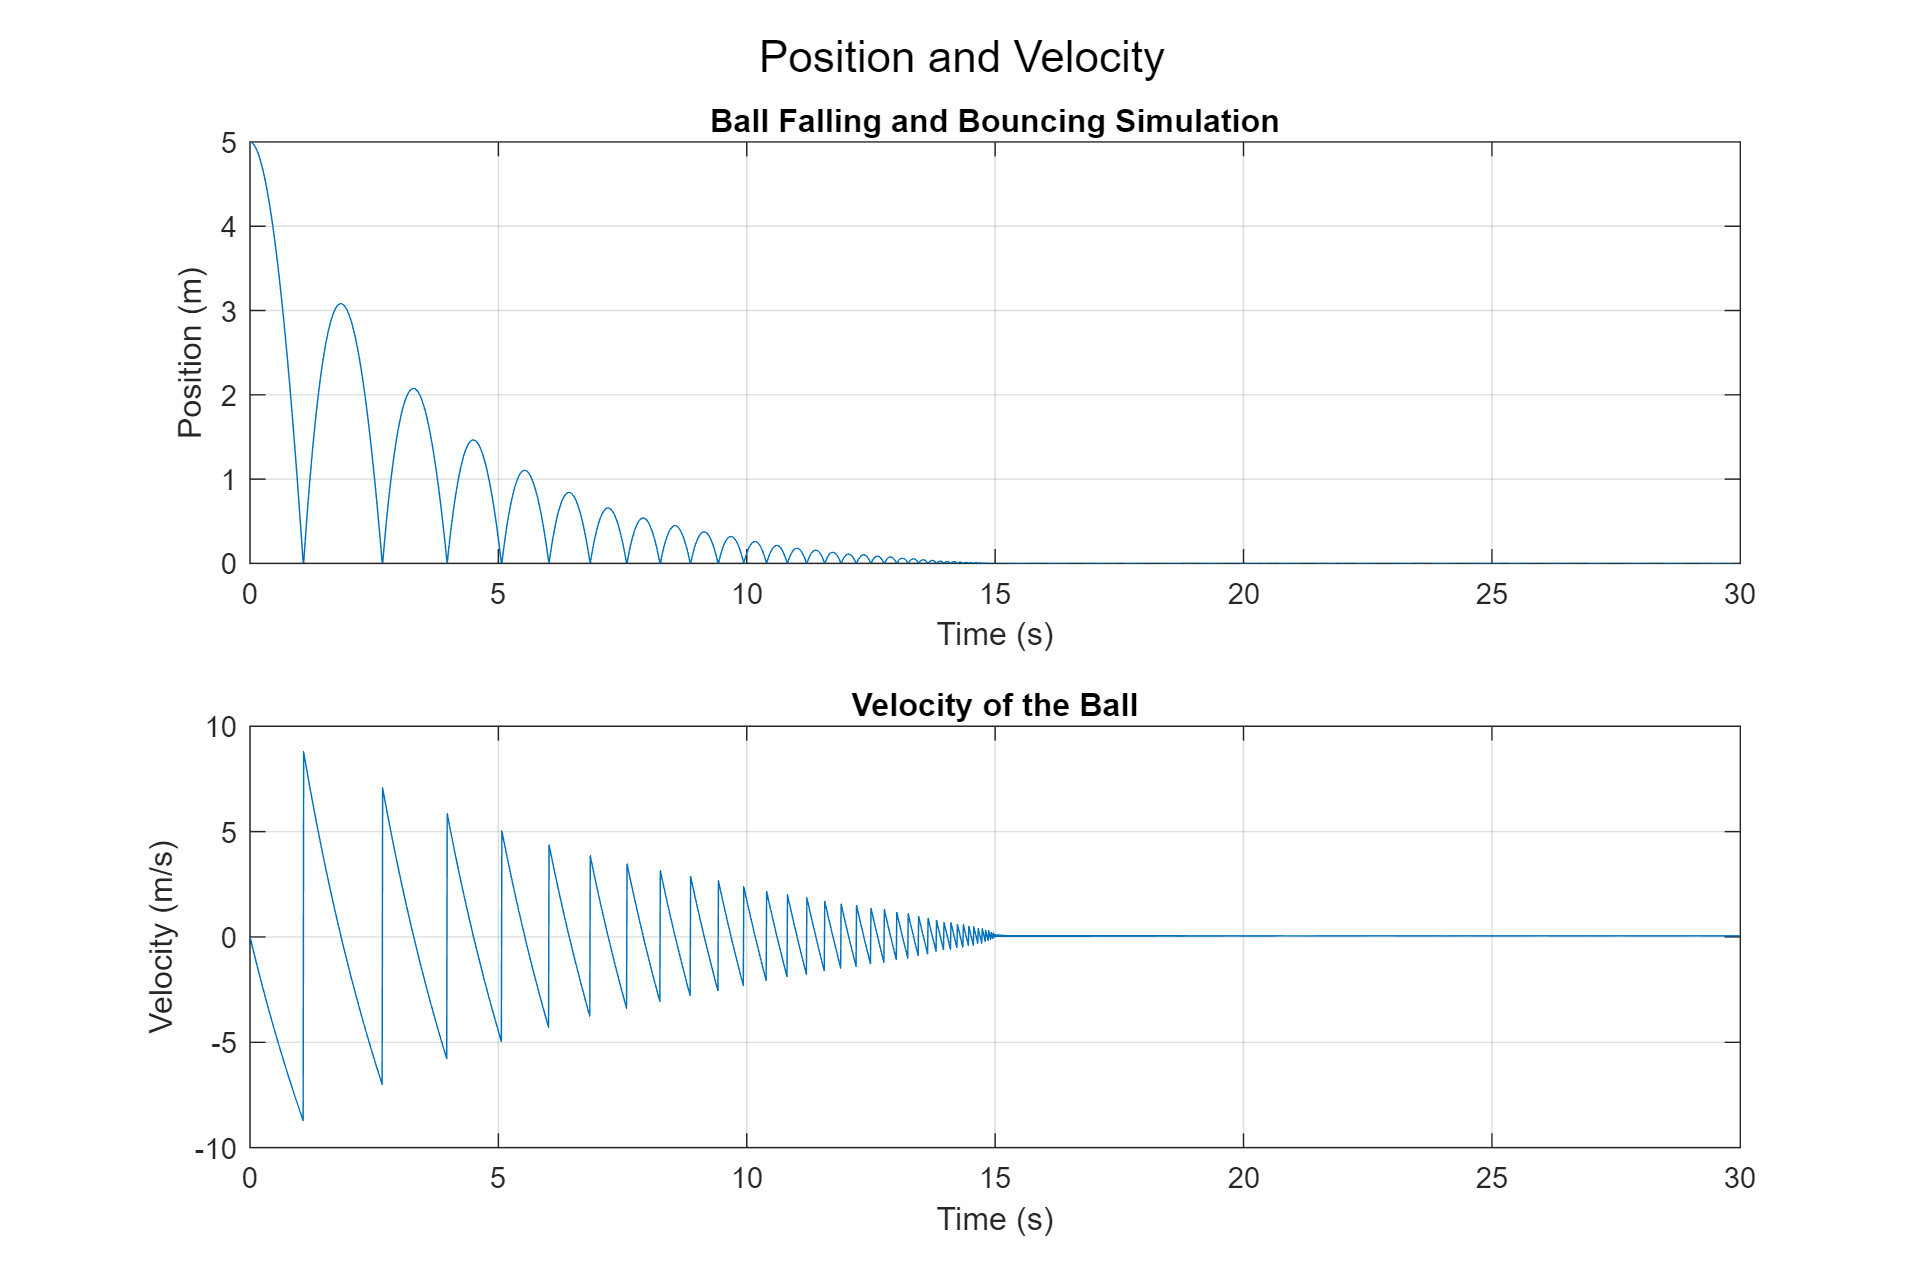

clear; 
clf; 

% Parameters
m = 0.5;    % mass of the ball
g = 9.82;    % acceleration due to gravity
b = 0.2;    % elasticity coefficient
rho = 1.2;  % air density - för 0 m.ö.h
A = 0.01;   % cross-sectional area of the ball
C = 0.47;   % drag coefficient - standard for spherical objects
initial_velocity = 0;  % initial velocity
initial_position = 5;  % initial position (drop height)

% Time parameters
h = 0.01;  % time step (for euler)
t_max = 30; % simulation time (s)

% Simulation
t = 0:h:t_max;
v = zeros(size(t));
y = zeros(size(t));

v(1) = initial_velocity;
y(1) = initial_position;

for i = 2:length(t)
    % Gravity term
    F_gravity = -m * g;
    
    % Elasticity term
    F_elasticity = -b * v(i-1);
    
    % Drag term
    D = -0.5 * C * rho * A * v(i-1)^2;
    
    % Total force
    F_total = F_gravity + F_elasticity + D;
    
    % Update velocity and position using Euler's method
    v(i) = v(i-1) + (F_total / m) * h;
    y(i) = y(i-1) + v(i) * h;
    
    % Bounce condition (e.g., reverse velocity when hitting the ground)
    if y(i) < 0
        y(i) = 0;      % Set position to ground level
        v(i) = -v(i);  % Reverse velocity
    end
end

% Plot the results
figure;

% Position plot
subplot(2, 1, 1);
plot(t, y);
title('Ball Falling and Bouncing Simulation');
xlabel('Time (s)');
ylabel('Position (m)');
grid on;

% Velocity plot
subplot(2, 1, 2);
plot(t, v);
title('Velocity of the Ball');
xlabel('Time (s)');
ylabel('Velocity (m/s)');
grid on;

% Adjust the layout to prevent overlapping
sgtitle('Position and Velocity');

% Adjust the position of the subplots for better visibility
set(gcf, 'Position', get(0, 'Screensize')); 